
$$\dot x = f(x)   \Rightarrow x(t+\Delta t) = F(x(t))$$


1) $f(x) = -x$

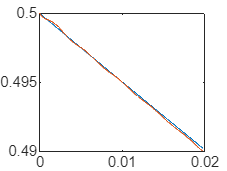

clear; close all;
m = 2053; % No. of observables
delt = 0.001/m;
t = 0:delt:10000*delt;
x0 = 0.5;
x = x0*exp(-t);


Xi = zeros(m,length(t));
Xi(1,1) = 1; 
for i = 1:(m-1)/2
    Xi(2*i,1) = cos(2*pi*i*x0);
    Xi(2*i+1,1) = sin(2*pi*i*x0);
end
A = A_negx(m,delt);
for i = 1:length(t)-1
    Xi(:,i+1) = A*Xi(:,i);
end
x_est = recover_x(Xi);
plot(t,x)
hold on
plot(t, x_est)% '-o', 'MarkerSize', 5, 'MarkerFaceColor', 'red', 'LineWidth', 1.2)
hold off

2) $f(x) = Ax$

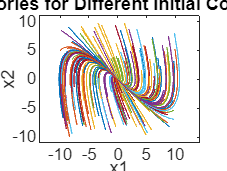

clear; close all;
delt = 0.01;
A = [0 1; -2 -3];
t = (0:delt:10)';  % Time vector

% Generate 100 random initial conditions in the range [-10, 10]
num_ICs = 200;
x0_all = -10 + (20)*rand(num_ICs, 2);  % num_ICs x 2 matrix with values in [-10, 10]

% Preallocate matrices for trajectories (x1 and x2)
x1 = zeros(num_ICs, length(t));  % num_ICs x timesteps
x2 = zeros(num_ICs, length(t));  % num_ICs x timesteps

% Loop through each initial condition
for j = 1:num_ICs
    x0 = x0_all(j, :)';  % Get the initial condition for the current IC
    for i = 1:length(t)
        x = expm(A*t(i)) * x0;  % Solve system for each time step
        x1(j, i) = x(1);  % Store x1 trajectory
        x2(j, i) = x(2);  % Store x2 trajectory
    end
end

% Plot the trajectories for visualization
figure;
for j = 1:num_ICs
    plot(x1(j,:), x2(j, :)); hold on;  % Plot x1 trajectories
end
xlabel('x1');
ylabel('x2');
axis([-11 11 -11 11])
axis equal
title('Trajectories for Different Initial Conditions');
hold off;


% Combine x1 and x2 into a single data matrix for clustering
data = [reshape(x1, [], 1), reshape(x2, [], 1)];  % (num_ICs*timesteps) x 2 matrix

% Specify the number of clusters (RBF kernel centers)
num_clusters = 50;  % You can modify this number based on your application

% Apply k-means++ clustering to find the RBF kernel centers
[idx, centers] = kmeans(data, num_clusters, 'Start', 'plus', 'Replicates', 1);

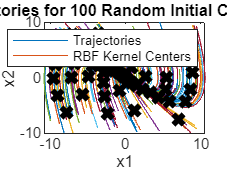


% Plot the trajectories for visualization
figure;
for j = 1:num_ICs
    plot(x1(j,:), x2(j, :)); hold on;  % Plot x1 vs x2 trajectories
end
xlabel('x1');
ylabel('x2');
title('Trajectories for 100 Random Initial Conditions');

% Plot the cluster centers
plot(centers(:,1), centers(:,2), 'kx', 'MarkerSize', 8, 'LineWidth', 3);  % Plot RBF centers
legend('Trajectories', 'RBF Kernel Centers');
hold off;

tic
A = lin_system(delt, centers);
disp("Time taken for inner product computation : "+toc)

Time taken for inner product computation : 35.09


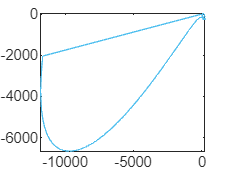

m = size(centers,1);
Xi = zeros(m, length(t));x_est = zeros(2,length(t));
x0 = [4 ; 6];
for i = 1:m
    sigma = 1; c = (centers(i,:))';
    Xi(i,1) = exp(-((x0 - c)' * (x0 - c)) / (2 * sigma^2)); 
end
for i = 1:length(t)-1
    Xi(:,i+1) = A*Xi(:,i);
    x_est(:,i) = recover_x_from_RBF(Xi(:,i), centers);
end

A_lin = [0 1; -2 -3];
x_est(:,end) = recover_x_from_RBF(Xi(:,end), centers);
for i = 1:length(t)
    x(:,i) = expm(A_lin*t(i)) * x0;  % Solve system for each time step
end
plot(x(1,:),x(2,:))
hold on
plot(x_est(1,:),x_est(2,:))